clc;
clear;
close all;
format long g

%% PLANTA DE VELOCIDAD

Km = 0.90907;
tau = 0.28215;

num = Km;
den = [tau 1];

G = tf(num, den);

disp('Planta continua de velocidad:')

Planta continua de velocidad:


G


G =
 
     0.9091
  ------------
  0.2822 s + 1
 
Continuous-time transfer function.



%% ESPECIFICACIONES

zita = 0.9;
ts = 1;                   % Tiempo de establecimiento

wn = 4/(zita*ts);
wd = wn*sqrt(1-zita^2);

% Recomendacion del profesor
Tm = ts/20;
Tm1 = Tm/2;

fprintf('wn  = %.8f rad/s\n', wn);

wn  = 4.44444444 rad/s


fprintf('Tm  = %.8f s\n', Tm);

Tm  = 0.05000000 s


fprintf('Tm1 = %.8f s\n\n', Tm1);

Tm1 = 0.02500000 s




%% 1. CONTROLADOR DISCRETO-DISCRETO PI

G_z = c2d(G, Tm, 'zoh');

[numTF, denTF] = tfdata(G_z, 'v');

numTF = numTF/denTF(1);
denTF = denTF/denTF(1);

a1 = denTF(2);
b1 = numTF(end);

radio = exp(-zita*wn*Tm);
angulo = wd*Tm;

P1 = -2*radio*cos(angulo);
P2 = radio^2;

% Controlador:
% C(z) = (s0*z + s1)/(z + r1)
% Se coloca un integrador en z=1
r1 = -1;

s0 = (P1 - a1 + 1)/b1;
s1 = (P2 + a1)/b1;

C_DD = tf([s0 s1], [1 r1], Tm);
T_DD = feedback(C_DD*G_z, 1);

%% 2. CONTROLADOR CONTINUO-DISCRETO PI

kp = (2*zita*wn*tau - 1)/Km

kp =           1.38295180789158


ki = (wn^2*tau)/Km

ki =            6.1308076752432



Gc = tf([kp ki], [1 0]);
Gc_z = c2d(Gc, Tm, 'tustin');

[numCD, denCD] = tfdata(Gc_z, 'v');

numCD = numCD/denCD(1);
denCD = denCD/denCD(1);

c1 = numCD(1);
c0 = numCD(2);
ra = denCD(2);

T_CD = feedback(Gc_z*G_z, 1);

%% 3. CONTROLADOR POR LGR

% Compensador:
% C(z) = K*(z + alpha)/(z + bc)
%
% Para eliminar el error estacionario se coloca
% el polo del controlador en z=1.

bc = -1;

K = (P1 - a1 + 1)/b1;
alpha = (P2 + a1)/(K*b1);

C_LGR = tf(K*[1 alpha], [1 bc], Tm);
T_LGR = feedback(C_LGR*G_z, 1);

%% 4. CONTROLADOR DE OSCILACIONES MUERTAS

G_z_os = c2d(G, Tm1, 'zoh');

[numOS, denOS] = tfdata(G_z_os, 'v');

numOS = numOS/denOS(1);
denOS = denOS/denOS(1);

bOS = numOS(end);
aOS = denOS(2);

% Controlador deadbeat:
% C(z) = Kos*(z + aa1)/(z + bb3)

Kos = 1/bOS;
aa1 = aOS;
bb3 = -1;

C_OS = tf(Kos*[1 aa1], [1 bb3], Tm1);
T_OS = feedback(C_OS*G_z_os, 1);

%% RESULTADOS

fprintf('\nDISCRETO-DISCRETO:\n');


DISCRETO-DISCRETO:


fprintf('s0 = %.8f, s1 = %.8f, r1 = %.8f\n', s0, s1, r1);

s0 = 1.40769293, s1 = -1.13312504, r1 = -1.00000000


fprintf('u[k] = %.8f*u[k-1] %+.8f*e[k] %+.8f*e[k-1]\n', ...
        -r1, s0, s1);

u[k] = 1.00000000*u[k-1] +1.40769293*e[k] -1.13312504*e[k-1]



fprintf('\nCONTINUO-DISCRETO:\n');


CONTINUO-DISCRETO:


fprintf('kp = %.8f, ki = %.8f\n', kp, ki);

kp = 1.38295181, ki = 6.13080768


fprintf('c1 = %.8f, c0 = %.8f, ra = %.8f\n', c1, c0, ra);

c1 = 1.53622200, c0 = -1.22968162, ra = -1.00000000


fprintf('u[k] = %.8f*u[k-1] %+.8f*e[k] %+.8f*e[k-1]\n', ...
        -ra, c1, c0);

u[k] = 1.00000000*u[k-1] +1.53622200*e[k] -1.22968162*e[k-1]



fprintf('\nLGR:\n');


LGR:


fprintf('K = %.8f, alpha = %.8f, bc = %.8f\n', K, alpha, bc);

K = 1.40769293, alpha = -0.80495186, bc = -1.00000000


fprintf('u[k] = %.8f*u[k-1] %+.8f*e[k] %+.8f*e[k-1]\n', ...
        -bc, K, K*alpha);

u[k] = 1.00000000*u[k-1] +1.40769293*e[k] -1.13312504*e[k-1]



fprintf('\nOSCILACIONES MUERTAS:\n');


OSCILACIONES MUERTAS:


fprintf('Kos = %.8f, aa1 = %.8f, bb3 = %.8f\n', Kos, aa1, bb3);

Kos = 12.97301947, aa1 = -0.91520669, bb3 = -1.00000000


fprintf('u[k] = %.8f*u[k-1] %+.8f*e[k] %+.8f*e[k-1]\n', ...
        -bb3, Kos, Kos*aa1);

u[k] = 1.00000000*u[k-1] +12.97301947*e[k] -11.87299417*e[k-1]


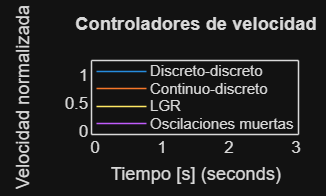


%% COMPARACION

figure;
step(T_DD, T_CD, T_LGR, T_OS, 3*ts);
grid on;
legend('Discreto-discreto', ...
       'Continuo-discreto', ...
       'LGR', ...
       'Oscilaciones muertas', ...
       'Location', 'best');
title('Controladores de velocidad');
xlabel('Tiempo [s]');
ylabel('Velocidad normalizada');